 EJECUTANDO CONFIGURACIÓN: [3 x 3] (9 clases)


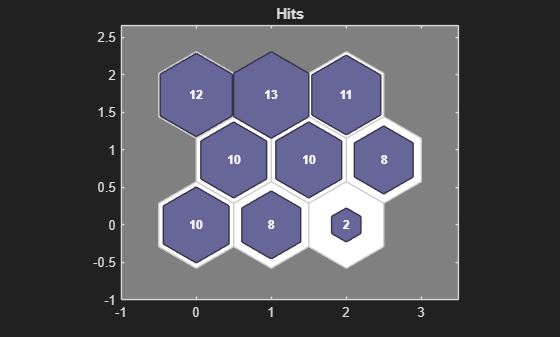

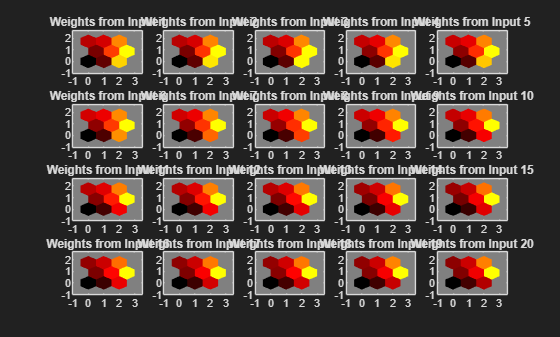

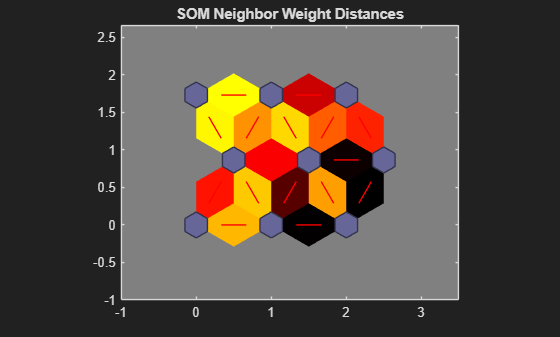

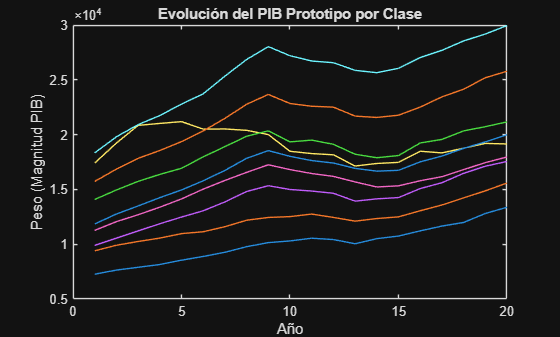


COMPOSICIÓN DE CLASES (Caso 1 - Total):


         ProvM1                 ProvM2                ProvM3             ProvM4                ProvM5                        ProvM6                            ProvM7                             ProvM8                                ProvM9                               ProvM10                     ProvM11         ProvM12           ProvM13           ProvM14         ProvM15         ProvM16         ProvM17         ProvM18         ProvM19         ProvM20   
    _________________    _____________________    _______________    _______________    _____________________    

Análisis de pesos: La Clase 6 tiene el PIB promedio más alto, la Clase 1 el más bajo.


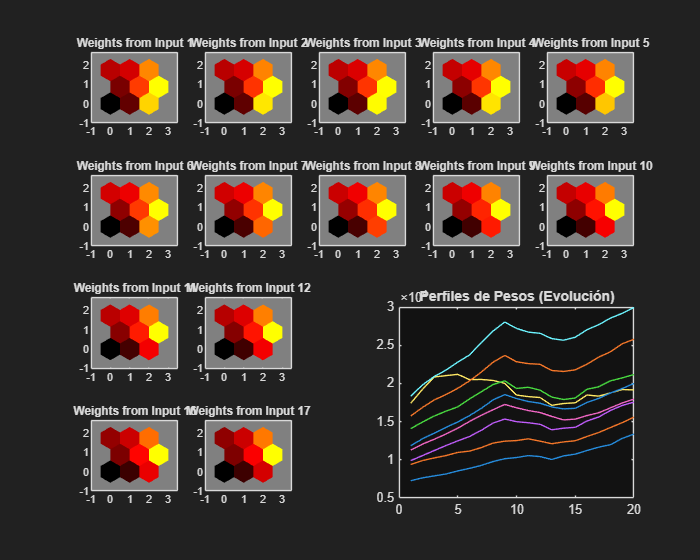

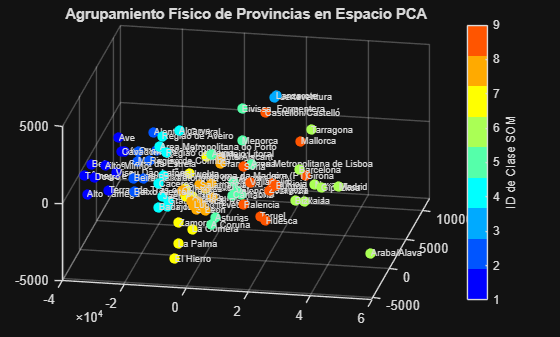

 EJECUTANDO CONFIGURACIÓN: [4 x 4] (16 clases)


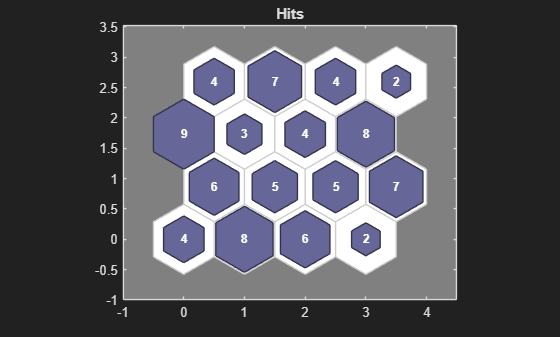

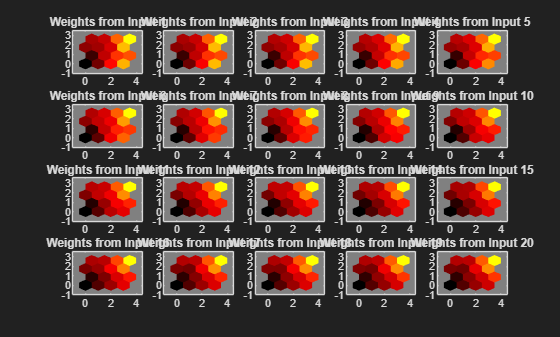

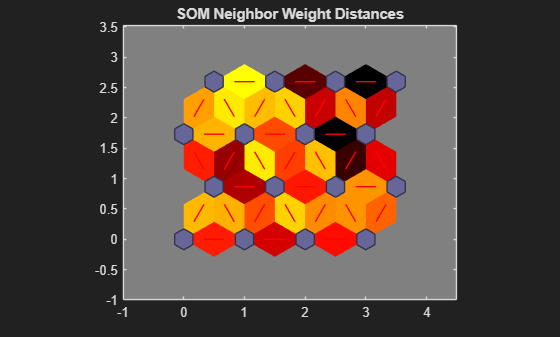

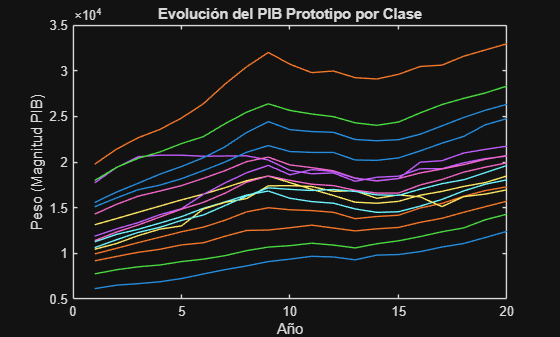


COMPOSICIÓN DE CLASES (Caso 1 - Total):


         ProvM1                 ProvM2                   ProvM3                       ProvM4                        ProvM5                        ProvM6                              ProvM7                               ProvM8                                 ProvM9                     ProvM10         ProvM11         ProvM12         ProvM13         ProvM14         ProvM15         ProvM16         ProvM17         ProvM18         ProvM19         ProvM20   
    _________________    _____________________    _____________________    _____________________________    ____________________

Análisis de pesos: La Clase 16 tiene el PIB promedio más alto, la Clase 1 el más bajo.


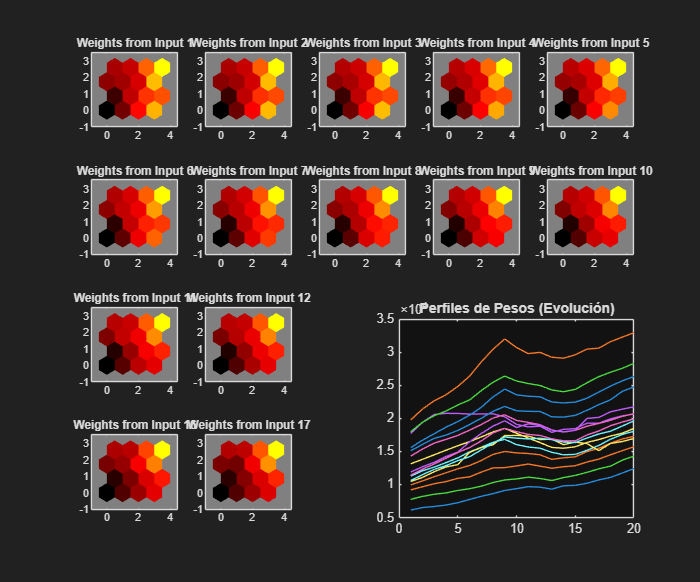

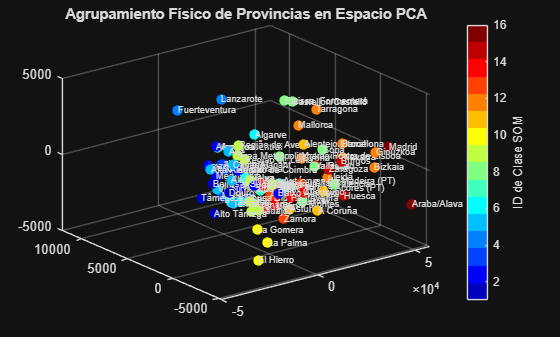

 EJECUTANDO CONFIGURACIÓN: [2 x 5] (10 clases)


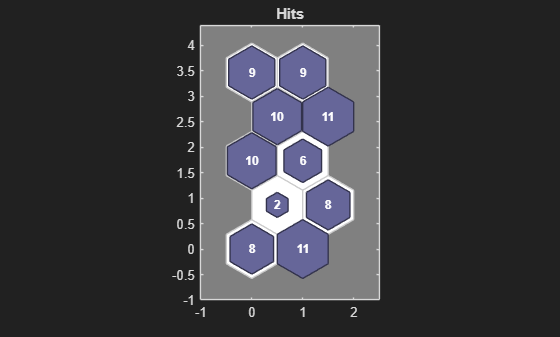

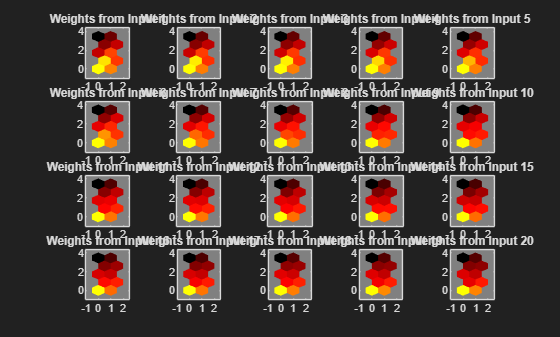

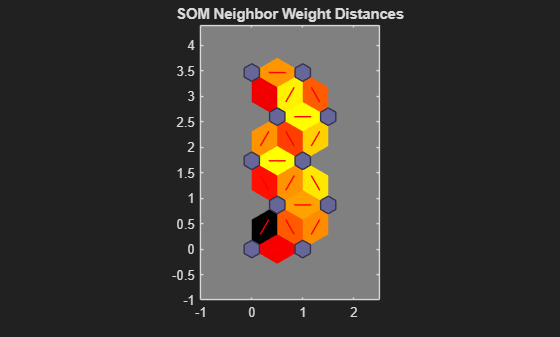

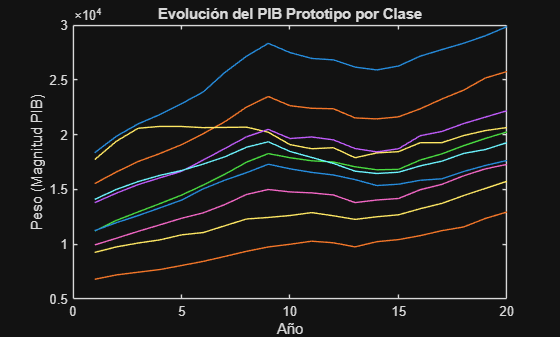


COMPOSICIÓN DE CLASES (Caso 1 - Total):


         ProvM1             ProvM2               ProvM3                   ProvM4                  ProvM5                        ProvM6                              ProvM7                            ProvM8                              ProvM9                                 ProvM10                    ProvM11         ProvM12         ProvM13         ProvM14         ProvM15         ProvM16         ProvM17         ProvM18         ProvM19         ProvM20   
    _________________    _____________    _____________________    ____________________    _____________________    

Análisis de pesos: La Clase 1 tiene el PIB promedio más alto, la Clase 9 el más bajo.


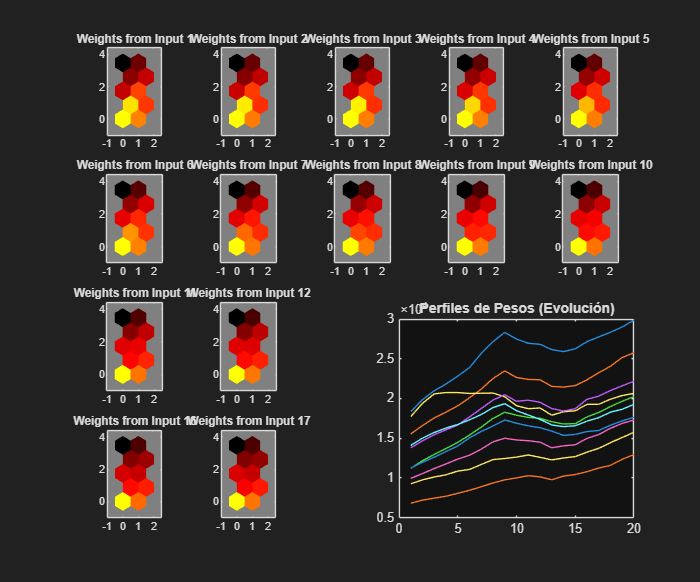

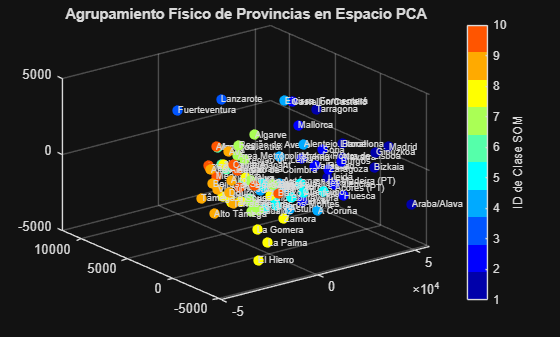

 EJECUTANDO CONFIGURACIÓN: [3 x 5] (15 clases)


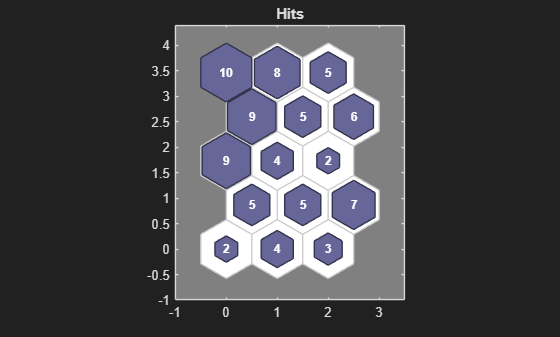

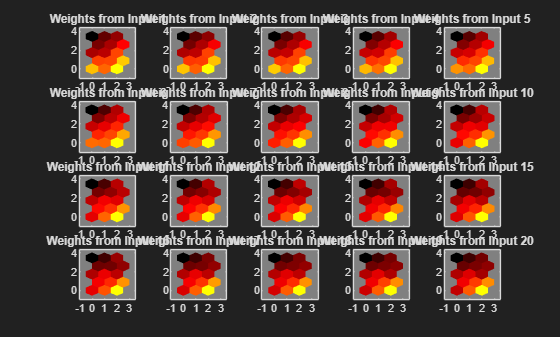

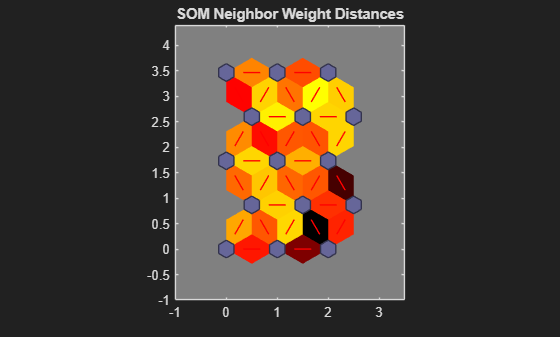

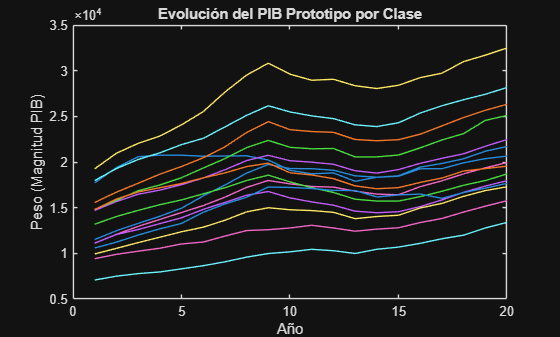


COMPOSICIÓN DE CLASES (Caso 1 - Total):


         ProvM1                 ProvM2                   ProvM3                    ProvM4                          ProvM5                             ProvM6                            ProvM7                             ProvM8                                 ProvM9                        ProvM10           ProvM11         ProvM12         ProvM13         ProvM14         ProvM15         ProvM16         ProvM17         ProvM18         ProvM19         ProvM20   
    _________________    _____________________    _____________________    _______________________    _____________________

Análisis de pesos: La Clase 3 tiene el PIB promedio más alto, la Clase 13 el más bajo.


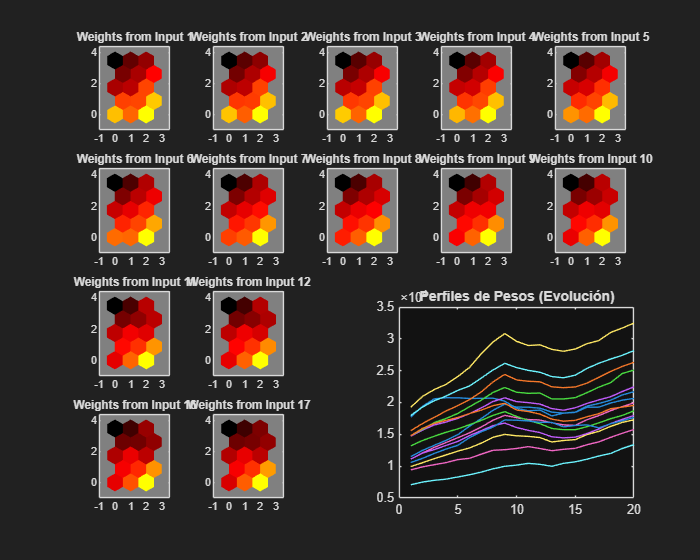

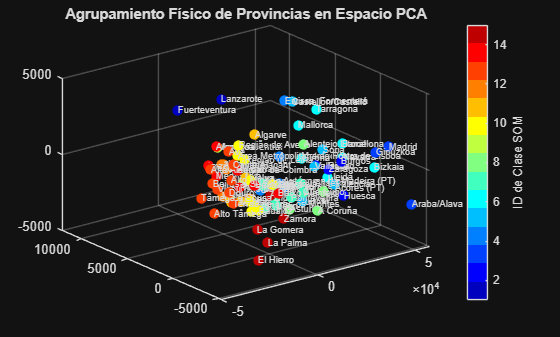

 EJECUTANDO CONFIGURACIÓN: [4 x 5] (20 clases)


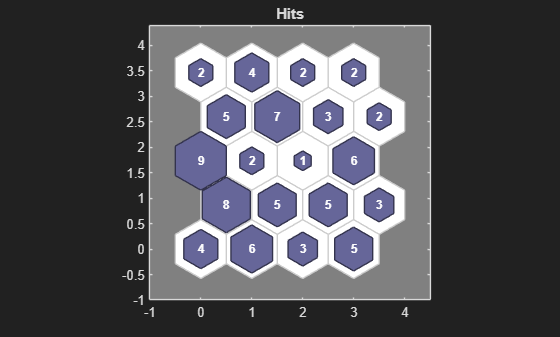

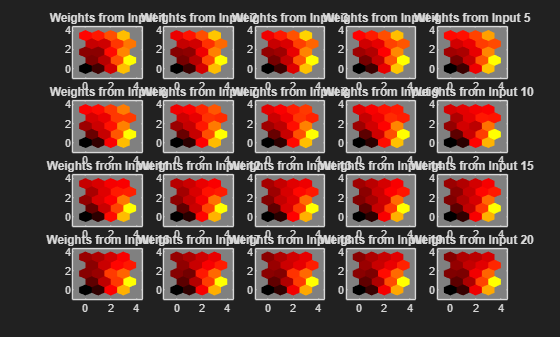

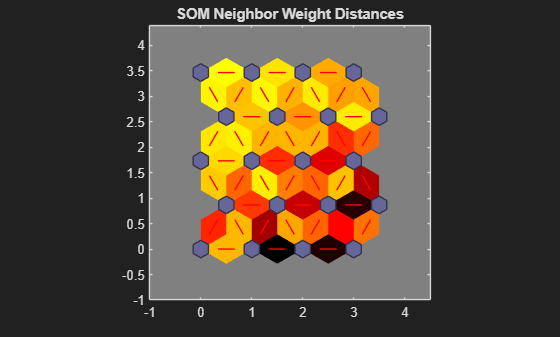

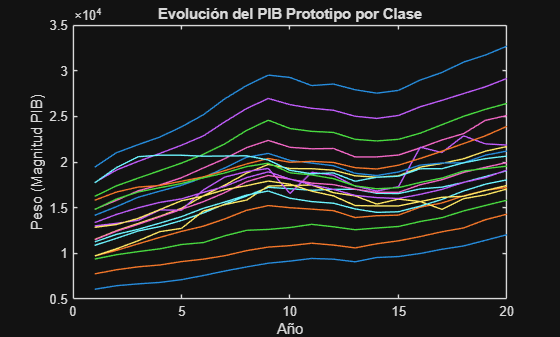


COMPOSICIÓN DE CLASES (Caso 1 - Total):


            ProvM1                          ProvM2                        ProvM3                       ProvM4                        ProvM5                        ProvM6                        ProvM7                         ProvM8                                 ProvM9                     ProvM10         ProvM11         ProvM12         ProvM13         ProvM14         ProvM15         ProvM16         ProvM17         ProvM18         ProvM19         ProvM20   
    _______________________    ________________________________    _____________________    _____________________________    

Análisis de pesos: La Clase 8 tiene el PIB promedio más alto, la Clase 1 el más bajo.


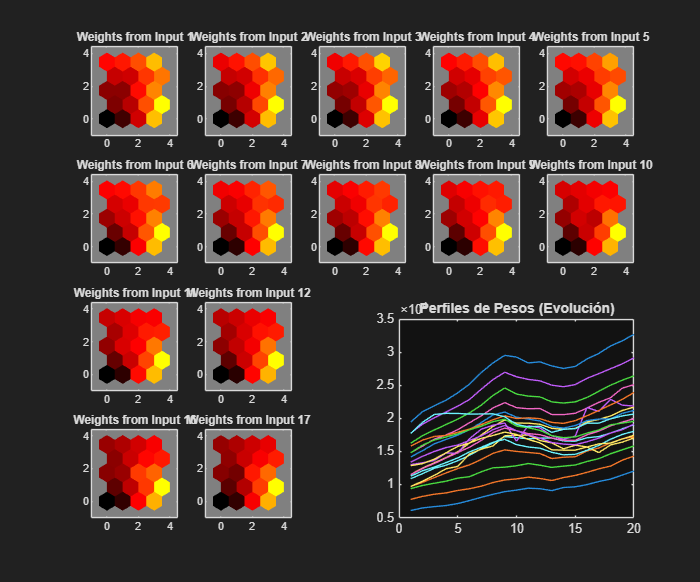

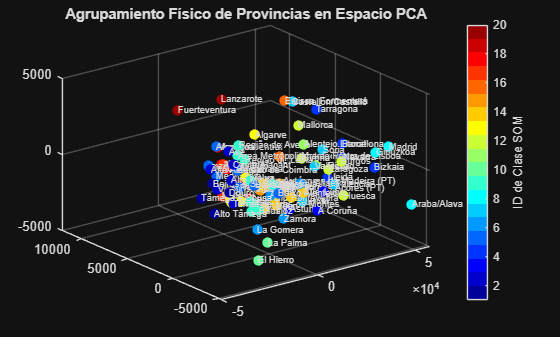

 EJECUTANDO CONFIGURACIÓN: [5 x 5] (25 clases)


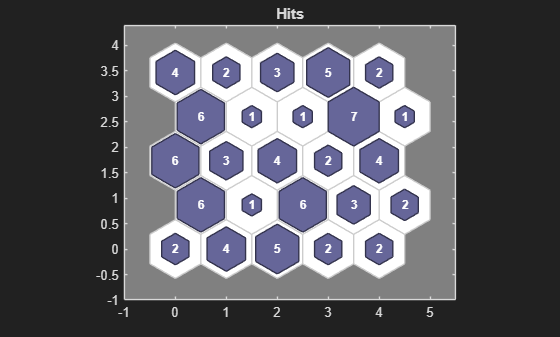

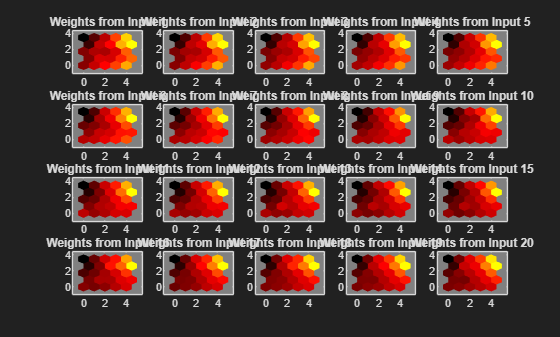

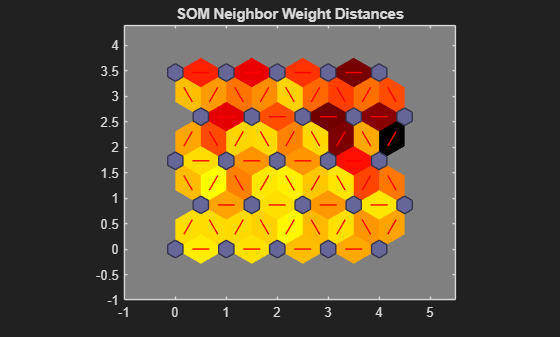

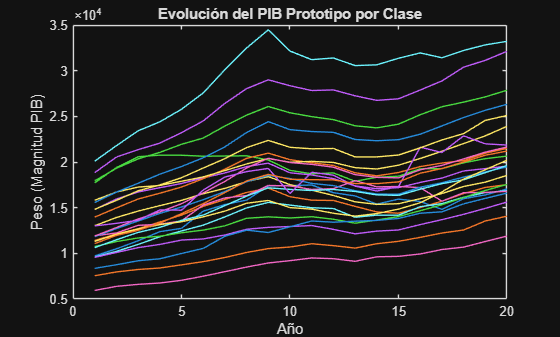


COMPOSICIÓN DE CLASES (Caso 1 - Total):


                ProvM1                              ProvM2                        ProvM3                       ProvM4                        ProvM5                          ProvM6                      ProvM7          ProvM8          ProvM9         ProvM10         ProvM11         ProvM12         ProvM13         ProvM14         ProvM15         ProvM16         ProvM17         ProvM18         ProvM19         ProvM20   
    _______________________________    ________________________________    _____________________    _____________________________    ______________________ 

Análisis de pesos: La Clase 20 tiene el PIB promedio más alto, la Clase 21 el más bajo.


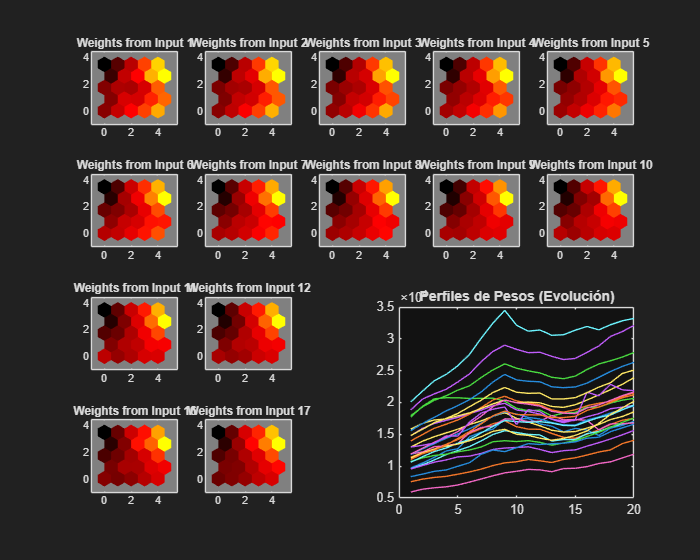

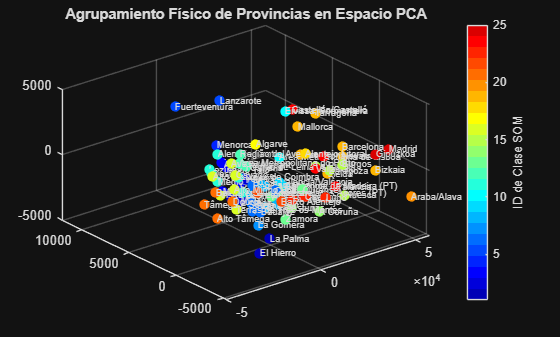

clear all; close all; clc;

% --- CARGA DE DATOS ---
[datos_raw, provincias_raw] = xlsread('PPSyVAB.xlsx', 'VABpc', 'A2:U85');
datos = datos_raw'; 
provincias = provincias_raw';
n_total = size(datos, 2);

% --- CONFIGURACIONES A PROBAR ---
configs = {[3,3], [4,4], [2,5], [3,5], [4,5], [5,5]}; % Diferentes números de neuronas [cite: 20]

% Análisis PCA previo para reducción de componentes 
[~, score, latent] = pca(datos');
d_pca = score(:, 1:3)'; 

for c = 1:length(configs)
    tam = configs{c};
    n_clases = tam(1) * tam(2);
    fprintf('\n======================================================\n');
    fprintf(' EJECUTANDO CONFIGURACIÓN: [%d x %d] (%d clases)\n', tam(1), tam(2), n_clases);
    
    % --- CASO 1: Agrupamiento Total ---
    red1 = selforgmap(tam);
    red1.trainParam.showWindow = false;
    red1 = train(red1, datos);
    clases1 = vec2ind(red1(datos));


    % --- VISUALIZACIÓN DETALLADA DE LA RED (CASO 1) ---
    % Se crean figuras independientes para cada gráfico de diagnóstico del SOM
    
    % 1. Hits: Distribución de muestras en las neuronas [cite: 16]
    figure('Name', 'SOM Sample Hits');
    plotsomhits(red1, datos); 

    % 2. Input Planes: Visualización de los pesos para cada año (20 planos) [cite: 25, 32]
    figure('Name', 'SOM Input Planes');
    plotsomplanes(red1); 

    % 3. Neighbor Distances: Distancias de U-Matrix (ayuda a ver fronteras entre grupos) [cite: 15]
    figure('Name', 'SOM Neighbor Distances');
    plotsomnd(red1); 

    % 4. Weight Profiles: Evolución temporal de los pesos (prototipos de PIB) 
    figure('Name', 'Weight Profiles');
    plot(red1.IW{1}'); 
    title('Evolución del PIB Prototipo por Clase');
    xlabel('Año'); ylabel('Peso (Magnitud PIB)');


    % --- CASO 2: Barajado y Clasificación (70% / 30%) [cite: 21, 24] ---
    idx = randperm(n_total);
    d_ent = datos(:, idx(1:round(0.7*n_total)));
    red2 = selforgmap(tam);
    red2.trainParam.showWindow = false;
    red2 = train(red2, d_ent);
    clases2_all = vec2ind(red2(datos(:, idx)));
    [~, inv_idx] = sort(idx);
    clases2_final = clases2_all(inv_idx);

    % --- CASO 3: Reducción (Entrenamiento con PCA)  ---
    red3 = selforgmap(tam);
    red3.trainParam.showWindow = false;
    red3 = train(red3, d_pca);
    clases3 = vec2ind(red3(d_pca));

    % --- GENERACIÓN DE TABLA DE COMPOSICIÓN  ---
    fprintf('\nCOMPOSICIÓN DE CLASES (Caso 1 - Total):\n');
    ProvM = cell(n_clases, 20); % Tabla vacía para llenar
    for i = 1:n_clases
        miembros = provincias(clases1 == i);
        for j = 1:length(miembros)
            ProvM{i,j} = miembros{j};
        end
    end
    T_Clases = cell2table(ProvM);
    disp(T_Clases);

    % --- ANÁLISIS DE MATRICES DE PESOS  ---
    pesos_finales = red1.IW{1}; % Matriz de pesos
    [max_pib, clase_rica] = max(mean(pesos_finales, 2));
    [min_pib, clase_pobre] = min(mean(pesos_finales, 2));
    fprintf('Análisis de pesos: La Clase %d tiene el PIB promedio más alto, la Clase %d el más bajo.\n', clase_rica, clase_pobre);

    % --- VISUALIZACIÓN DE RESULTADOS ---
    
    % 1. Gráficos de entrenamiento estándar de Matlab 
    figure('Name', sprintf('Plots de Entrenamiento - Red %dx%d', tam(1), tam(2)));
    subplot(2,2,1); plotsomhits(red1, datos); title('Hits (Distribución)');
    subplot(2,2,2); plotsomnd(red1); title('Distancia entre Vecinos');
    subplot(2,2,3); plotsomplanes(red1); title('Planos de Entrada (Años)');
    subplot(2,2,4); plot(pesos_finales'); title('Perfiles de Pesos (Evolución)');

    % 2. PCA coloreado por los clusters del SOM
    figure('Name', sprintf('PCA coloreado por SOM %dx%d', tam(1), tam(2)));
    scatter3(score(:,1), score(:,2), score(:,3), 60, clases1, 'filled');
    text(score(:,1), score(:,2), score(:,3), provincias, 'FontSize', 7);
    colormap(jet(n_clases)); cb = colorbar; ylabel(cb, 'ID de Clase SOM');
    title('Agrupamiento Físico de Provincias en Espacio PCA');
    grid on;
end